# 2.a

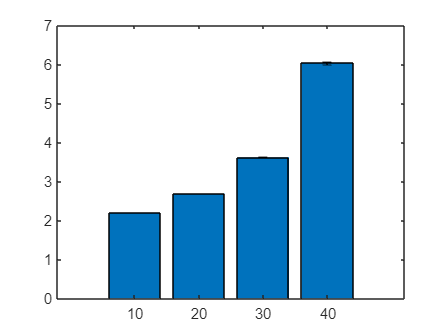

P = 10000;
conf = 0.9;
lambda = 1500;
C = 10;
f = 1e6;
N = 50;
n = 10;

PacketLossdata = zeros(1,N);
PacketLossvoip = zeros(1,N);

AvgPacketDelaydata = zeros(1,N);
AvgPacketDelayvoip = zeros(1,N);

MaxPacketDelaydata = zeros(1,N);
MaxPacketDelayvoip = zeros(1,N);

Throughput = zeros(1,N);

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator3(lambda,C,f,P,n);
end

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

R1d = [mAPDd];
R2d = [term2d];

R1v = [mAPDv];
R2v = [term2v];

% -------------------------------------------------------------- %
n = 20;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator3(lambda,C,f,P,n);
end

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

R1d = [R1d; mAPDd];
R2d = [R2d; term2d];

R1v = [R1v; mAPDv];
R2v = [R2v; term2v];

% -------------------------------------------------------------- %
n = 30;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator3(lambda,C,f,P,n);
end

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

R1d = [R1d; mAPDd];
R2d = [R2d; term2d];

R1v = [R1v; mAPDv];
R2v = [R2v; term2v];


% -------------------------------------------------------------- %
n = 40;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator3(lambda,C,f,P,n);
end

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

R1d = [R1d; mAPDd];
R2d = [R2d; term2d];

R1v = [R1v; mAPDv];
R2v = [R2v; term2v];


n = [10 20 30 40];

bar(n, R1d)

hold on

er = errorbar(n, R1d, R2d, R2d);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off

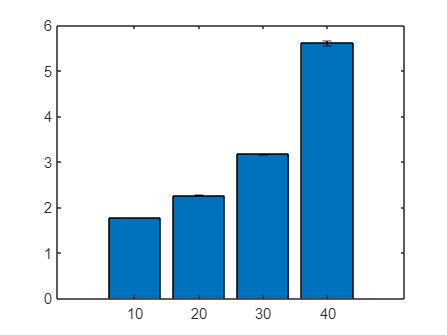


bar(n, R1v)

hold on

er = errorbar(n, R1v, R2v, R2v);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off

## 2b

P = 10000;
conf = 0.9;
lambda = 1500;
C = 10;
f = 1e6;
N = 50;
n = 10;

PacketLossdata = zeros(1,N);
PacketLossvoip = zeros(1,N);

AvgPacketDelaydata = zeros(1,N);
AvgPacketDelayvoip = zeros(1,N);

MaxPacketDelaydata = zeros(1,N);
MaxPacketDelayvoip = zeros(1,N);

Throughput = zeros(1,N);

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator4(lambda,C,f,P,n);
end

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

R1d = [mAPDd];
R2d = [term2d];

R1v = [mAPDv];
R2v = [term2v];

% -------------------------------------------------------------- %
n = 20;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator4(lambda,C,f,P,n);
end

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

R1d = [R1d; mAPDd];
R2d = [R2d; term2d];

R1v = [R1v; mAPDv];
R2v = [R2v; term2v];

% -------------------------------------------------------------- %
n = 30;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator4(lambda,C,f,P,n);
end

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

R1d = [R1d; mAPDd];
R2d = [R2d; term2d];

R1v = [R1v; mAPDv];
R2v = [R2v; term2v];


% -------------------------------------------------------------- %
n = 40;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator4(lambda,C,f,P,n);
end

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

R1d = [R1d; mAPDd];
R2d = [R2d; term2d];

R1v = [R1v; mAPDv];
R2v = [R2v; term2v];

n = [10 20 30 40];

bar(n, R1d)

hold on

er = errorbar(n, R1d, R2d, R2d);
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

bar(n, R1v)

hold on

er = errorbar(n, R1v, R2v, R2v);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off


## 2c

## 2d

P = 10000;
conf = 0.9;
lambda = 1800;
C = 10;
f = 1e5;
N = 10;
n = 10;

PacketLossdata = zeros(1,N);
PacketLossvoip = zeros(1,N);

AvgPacketDelaydata = zeros(1,N);
AvgPacketDelayvoip = zeros(1,N);

MaxPacketDelaydata = zeros(1,N);
MaxPacketDelayvoip = zeros(1,N);

Throughput = zeros(1,N);

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator3(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);
mPLv = mean(PacketLossvoip);

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [mPLd];
RAPDd = [mAPDd];
Rt1d = [term1d];
Rt2d = [term2d];

%voIp packets
RPLv = [mPLv];
RAPDv = [mAPDv];
Rt1v = [term1v];
Rt2v = [term2v];

% -------------------------------------------------------------- %

n = 20;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator3(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);
mPLv = mean(PacketLossvoip);

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %
n = 30;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator3(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);
mPLv = mean(PacketLossvoip);

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %
n = 40;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator3(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);
mPLv = mean(PacketLossvoip);

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %


n = [10 20 30 40];

% data packets

bar(n, RPLd)

hold on

er = errorbar(n, RPLd, Rt1d, Rt1d);
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

bar(n, RAPDd)

hold on

er = errorbar(n, RAPDd, Rt2d, Rt2d);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off

% voIp packets

bar(n, RPLv)

hold on

er = errorbar(n, RPLv, Rt1v, Rt1v);
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

bar(n, RAPDv)

hold on

er = errorbar(n, RAPDv, Rt2v, Rt2v);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off




## 2e

P = 10000;
conf = 0.9;
lambda = 1800;
C = 10;
f = 1e5;
N = 10;
n = 10;

PacketLossdata = zeros(1,N);
PacketLossvoip = zeros(1,N);

AvgPacketDelaydata = zeros(1,N);
AvgPacketDelayvoip = zeros(1,N);

MaxPacketDelaydata = zeros(1,N);
MaxPacketDelayvoip = zeros(1,N);

Throughput = zeros(1,N);

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator4(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);
mPLv = mean(PacketLossvoip);

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [mPLd];
RAPDd = [mAPDd];
Rt1d = [term1d];
Rt2d = [term2d];

%voIp packets
RPLv = [mPLv];
RAPDv = [mAPDv];
Rt1v = [term1v];
Rt2v = [term2v];

% -------------------------------------------------------------- %

n = 20;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator4(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);
mPLv = mean(PacketLossvoip);

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %
n = 30;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator4(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);
mPLv = mean(PacketLossvoip);

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %
n = 40;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator4(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);
mPLv = mean(PacketLossvoip);

mAPDd = mean(AvgPacketDelaydata);
mAPDv = mean(AvgPacketDelayvoip);

term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %


n = [10 20 30 40];

% data packets

bar(n, RPLd)

hold on

er = errorbar(n, RPLd, Rt1d, Rt1d);
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

bar(n, RAPDd)

hold on

er = errorbar(n, RAPDd, Rt2d, Rt2d);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off

% voIp packets

bar(n, RPLv)

hold on

er = errorbar(n, RPLv, Rt1v, Rt1v);
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

bar(n, RAPDv)

hold on

er = errorbar(n, RAPDv, Rt2v, Rt2v);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off



## 2f

P = 10000;
conf = 0.9;
lambda = 1800;
C = 10;
f = 1e5;
N = 10;
n = 10;

PacketLossdata = zeros(1,N);
PacketLossvoip = zeros(1,N);

AvgPacketDelaydata = zeros(1,N);
AvgPacketDelayvoip = zeros(1,N);

MaxPacketDelaydata = zeros(1,N);
MaxPacketDelayvoip = zeros(1,N);

Throughput = zeros(1,N);

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator5(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata)

mPLd = 0

mPLv = mean(PacketLossvoip)

mPLv = 0


mAPDd = mean(AvgPacketDelaydata)

mAPDd = 7.9495

mAPDv = mean(AvgPacketDelayvoip)

mAPDv = 0.5346


term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [mPLd];
RAPDd = [mAPDd];
Rt1d = [term1d];
Rt2d = [term2d];

%voIp packets
RPLv = [mPLv];
RAPDv = [mAPDv];
Rt1v = [term1v];
Rt2v = [term2v];

% -------------------------------------------------------------- %

n = 20;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator5(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata)

mPLd = 0.1204

mPLv = mean(PacketLossvoip)

mPLv = 0


mAPDd = mean(AvgPacketDelaydata)

mAPDd = 25.5003

mAPDv = mean(AvgPacketDelayvoip)

mAPDv = 0.5588


term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %
n = 30;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator5(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata)

mPLd = 1.1219

mPLv = mean(PacketLossvoip)

mPLv = 0


mAPDd = mean(AvgPacketDelaydata)

mAPDd = 52.8830

mAPDv = mean(AvgPacketDelayvoip)

mAPDv = 0.5661


term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %
n = 40;

for i=1:N
    [PacketLossdata(i),PacketLossvoip(i),AvgPacketDelaydata(i),AvgPacketDelayvoip(i),MaxPacketDelaydata(i),MaxPacketDelayvoip(i),Throughput(i)] = Simulator5(lambda,C,f,P,n);
end

mPLd = mean(PacketLossdata);

mPLd = 3.8805

mPLv = mean(PacketLossvoip);

mPLv = 0


mAPDd = mean(AvgPacketDelaydata);

mAPDd = 72.3553

mAPDv = mean(AvgPacketDelayvoip);

mAPDv = 0.5703

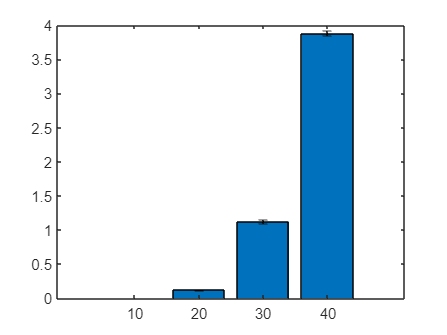


term1d = norminv(1-conf/2)*sqrt(var(PacketLossdata)/N);
term1v = norminv(1-conf/2)*sqrt(var(PacketLossvoip)/N);

term2d = norminv(1-conf/2)*sqrt(var(AvgPacketDelaydata)/N);
term2v = norminv(1-conf/2)*sqrt(var(AvgPacketDelayvoip)/N);

% data packets
RPLd = [RPLd; mPLd];
RAPDd = [RAPDd; mAPDd];
Rt1d = [Rt1d; term1d];
Rt2d = [Rt2d; term2d];

%voIp packets
RPLv = [RPLv; mPLv];
RAPDv = [RAPDv; mAPDv];
Rt1v = [Rt1v; term1v];
Rt2v = [Rt2v; term2v];

% -------------------------------------------------------------- %


n = [10 20 30 40];

% data packets

bar(n, RPLd)

hold on

er = errorbar(n, RPLd, Rt1d, Rt1d);
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

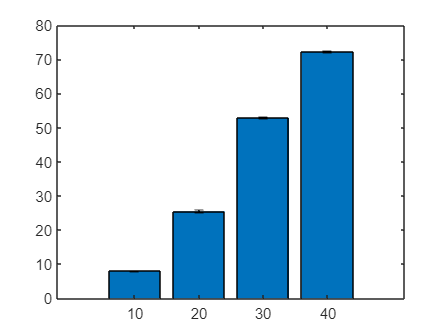


bar(n, RAPDd)

hold on

er = errorbar(n, RAPDd, Rt2d, Rt2d);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off

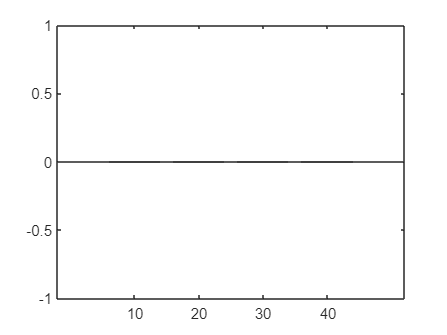


% voIp packets

bar(n, RPLv)

hold on

er = errorbar(n, RPLv, Rt1v, Rt1v);
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

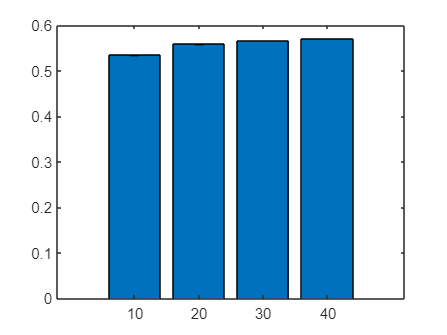


bar(n, RAPDv)

hold on

er = errorbar(n, RAPDv, Rt2v, Rt2v);
er.Color = [0 0 0];                            
er.LineStyle = 'none';

hold off